# Contribution 2 MATLAB Script

This script is used to import a raw Mindrove .csv file, append a binary class label, and export as a .txt file.

## Import Data and Standardize

Note: Must create column titled "timestamp_real" within csv file that changes timestamp column formatting: format -> custom->h:mm:ss->h:mm:ss.000

% File Selection
filename = ['8_11_36_05.csv']; %change this line before the .csv
tab = readtable(filename);
data = readmatrix(filename, 'NumHeaderLines', 1);

% Extract Data
time = tab.Timestamp_real(:,1); % cell array of time values
t = datetime(time,'InputFormat','mm:ss.SSS'); %datetime of time values
ch0_data = data(:,1);
ch1_data = data(:,2);
ch2_data = data(:,3);
ch3_data = data(:,4);
ch4_data = data(:,5);
ch5_data = data(:,6);
ch6_data = data(:,7);
ch7_data = data(:,8);
accx = data(:,11);
accy = data(:,12);
accz = data(:,13);

% Getting Acc in units of G [m^2/s]
accel_constant = 0.061035e-3; % constant converting Mindrove units to G
accx = accx*accel_constant;
accy = accy*accel_constant;
accz = accz*accel_constant;

% Getting EMG into units of muV
emg_constant = 0.045;        % constant converting Mindrove units to muV
ch0_data = ch0_data*emg_constant;
ch1_data = ch1_data*emg_constant;
ch2_data = ch2_data*emg_constant;
ch3_data = ch3_data*emg_constant;
ch4_data = ch4_data*emg_constant;
ch5_data = ch5_data*emg_constant;
ch6_data = ch6_data*emg_constant;
ch7_data = ch7_data*emg_constant;

%Time Calculations
t = posixtime(t);
t = t - t(1);

## Manually Label RTG Timestamps 

%Video Start Timestamp
timestampStr = input('Enter the timestamp (format: mm:ss:SSS): ', 's');

% Split the input string into its components
components = split(timestampStr, ':');

% Convert the components to numeric values
minutes = str2double(components{1});
seconds = str2double(components{2});
milliseconds = str2double(components{3});

% Calculate the total time in milliseconds
startMilliseconds = minutes*60*1000 + seconds*1000 + milliseconds;

% Convert totalMilliseconds to seconds
%totalSeconds = totalMilliseconds / 1000;

% Add totalSeconds to each element of t
%t_new = t + totalSeconds;


## Collect Timestamps

% Timestamps for Dish Washing 
% Dish washing 1
% offset = 00:04:340
%timestamps = ["00:11:850", "00:14:060", "00:17:670", "00:24:770", "00:33:590", "00:36:300", "00:39:300", "00:45:290", "00:52:250", "00:53:530", "00:56:810", "01:03:690", "01:09:500", "01:11:27", "01:14:040", "01:18:810", "01:25:280", "01:28:150", "01:31:010", "01:36:950", "01:43:600", "01:45:450", "01:48:300", "02:00:220", "02:01:710", "02:07:85", "02:15:030", "02:18:260", "02:23:560", "02:29:530", "02:30:750", "02:33:450", "2:40:35", "02:49:48", "02:50:92", "02:53:590", "02:55:010", "03:00:770", "03:07:200", "03:08:560", "03:10:980", "03:15:330", "03:20:620", "03:22:400", "03:30:850", "03:38:950", "03:41:320", "03:46:52", "03:52:820", "03:54:740", "03:59:600", "04:04:370", "04:05:980", "04:12:480", "04:17:710", "04:19:350", "04:23:960", "04:31:230", "04:32:800", "04:37:160", "04:46:000", "04:47:160", "04:52:650", "04:58:750", "05:00:410", "05:02:860", "05:08:590", "05:17:200", "05:18:750", "05:21:260", "05:25:530"]; %#ok<NASGU>
% Corrected
% timestamps = ["00:11:850", "00:14:060", "00:17:670", "00:33:590", "00:36:300", "00:39:300", "00:52:250", "00:53:530", "00:56:810", "01:09:500", "01:11:27", "01:14:040", "01:25:280", "01:28:150", "01:31:010", "01:43:600", "01:45:450", "02:00:220", "02:01:710", "02:15:030", "02:18:260", "02:29:530", "02:30:750", "02:33:450", "02:49:48", "02:50:92", "02:55:010", "03:07:200", "03:08:560", "03:10:980",  "03:20:620", "03:22:400", "03:38:950", "03:41:320", "03:52:820", "03:54:740", "04:04:370", "04:05:980", "04:17:710", "04:19:350", "04:31:230", "04:32:800", "04:46:000", "04:47:160", "04:58:750", "05:00:410", "05:02:860", "05:17:200", "05:18:750", "05:21:260"];


% Dish Washing 2
% offset = 00:07:720
% timestamps = ["00:14:410", "00:15:920", "00:19:610", "00:26:000", "00:33:650", "00:36:240", "00:42:220", "00:48:940", "00:51:300", "00:54:310", "01:00:220", "01:06:370", "01:08:170", "01:11:100", "01:16:310", "01:24:090", "01:25:630", "01:28:440", "01:35:930", "01:38:730", "01:40:00", "01:42:730", "01:48:090", "01:55:710", "01:57:170", "01:59:830", "02:04:590", "02:15:250", "02:16:420", "02:18:850", "02:22:580", "02:27:890", "02:37:810", "02:39:140", "02:41:190", "02:51:810", "02:53:270", "02:56:030", "02:57:590", "03:02:430", "03:10:710", "03:12:410", "03:14:790", "03:22:550", "03:29:710", "03:31:950", "03:34:520", "03:38:820", "03:49:830", "03:51:800", "03:57:520", "04:05:570", "04:07:58", "04:12:400", "04:19:560", "04:21:090", "04:26:640", "04:35:480", "04:37:050", "04:41:510", "04:47:880", "04:49:600", "04:54:960", "05:02:220", "05:04:940", "05:10:710", "05:17:470", "05:19:220", "05:24:380", "05:33:440", "05:34:960", "05:40:500"]
% Corrected
% timestamps = ["00:14:410", "00:15:920", "00:19:610", "00:33:650", "00:36:240", "00:48:940", "00:51:300", "00:54:310", "01:06:370", "01:08:170", "01:11:100",  "01:24:090", "01:25:630", "01:28:440", "01:38:730", "01:40:00", "01:42:730", "01:55:710", "01:57:170", "01:59:830", "02:15:250", "02:16:420", "02:22:580", "02:37:810", "02:39:140", "02:51:810", "02:53:270", "02:56:030", "02:57:590", "03:10:710", "03:12:410", "03:14:790", "03:29:710", "03:31:950", "03:34:520", "03:49:830", "03:51:800", "04:05:570", "04:07:58", "04:12:400", "04:19:560", "04:21:090", "04:35:480", "04:37:050", "04:47:880", "04:49:600", "05:02:220", "05:04:940", "05:17:470", "05:19:220", "05:33:440", "05:34:960"]

% Dish Washing 3
% offset = 00:03:310
% timestamps = ["00:08:790", "00:10:470", "00:13:450", "00:19:000", "00:27:500", "00:29:190", "00:31:870", "00:36:850", "00:42:920", "00:45:370", "00:47:680", "00:52:490", "00:58:950", "01:00:290", "01:02:900", "01:13:740", "01:18:450", "01:19:680", "01:22:270", "01:27:350", "01:35:860", "01:37:180", "01:40:350", "01:45:520", "01:52:590", "01:54:110", "01:56:490", "02:01:340", "02:08:480", "02:09:830", "02:12:610", "02:18:000", "02:23:350", "02:24:810", "02:29:910", "02:37:320", "02:38:350", "02:43:000", "02:49:680", "02:51:370", "02:53:760", "02:58:300", "03:05:500", "03:10:860", "03:16:130", "03:17:930", "03:22:270", "03:26:290", "03:32:090", "03:36:200", "03:37:860", "03:42:370", "03:47:200", "03:49:190", "03:53:160", "03:58:630", "04:00:500", "04:04:530", "04:10:000", "04:12:020", "04:16:310", "04:22:740", "04:24:570", "04:27:950", "04:38:680"]
% Corrected 
%timestamps = ["00:08:790", "00:10:470", "00:13:450", "00:27:500", "00:29:190", "00:31:870", "00:42:920", "00:45:370", "00:47:680", "00:58:950", "01:00:290", "01:02:900", "01:18:450", "01:19:680", "01:22:270", "01:35:860", "01:37:180", "01:40:350", "01:52:590", "01:54:110", "01:56:490", "02:08:480", "02:09:830", "02:12:610", "02:23:350", "02:24:810", "02:37:320", "02:38:350",  "02:49:680", "02:51:370", "02:53:760", "03:05:500", "03:16:130", "03:17:930", "03:22:270", "03:26:290", "03:36:200", "03:37:860", "03:47:200", "03:49:190", "03:58:630", "04:00:500", "04:10:000", "04:12:020", "04:22:740", "04:24:570", "04:38:680"]



% Dish Washing 4
% offset = 00:03:460
% timestamps = ["00:08:260", "00:09:480", "00:12:300", "00:17:460", "00:26:680", "00:28:830", "00:33:800", "00:39:800", "00:41:130", "00:46:030", "00:54:820", "00:55:870", "01:00:850", "01:07:120", "01:08:530", "01:14:340", "01:19:900", "01:21:240", "01:26:480", "01:32:760", "01:33:770", "01:39:940", "01:46:010", "01:47:470", "01:52:900", "01:59:680", "02:00:870", "02:03:400", "02:09:420", "02:18:340", "02:19:540", "02:25:040", "02:34:720", "02:36:350", "02:38:610", "02:44:050", "02:51:300", "02:52:810", "02:59:840", "03:07:820", "03:09:560", "03:18:010", "03:25:630", "03:27:150", "03:31:650", "03:37:670", "03:39:290", "03:44:450", "03:50:750", "03:52:050", "03:55:960", "04:00:830", "04:02:150", "04:06:900", "04:12:900", "04:14:340", "04:20:530", "04:25:800", "04:27:640", "04:32:650"]
% Corrected
% timestamps = ["00:08:260", "00:09:480", "00:12:300", "00:26:680", "00:28:830", "00:39:800", "00:41:130", "00:54:820", "00:55:870", "01:07:120", "01:08:530", "01:19:900", "01:21:240", "01:32:760", "01:33:770", "01:46:010", "01:47:470", "01:59:680", "02:00:870", "02:03:400", "02:18:340", "02:19:540", "02:34:720", "02:36:350", "02:38:610", "02:51:300", "02:52:810", "03:07:820", "03:09:560", "03:25:630", "03:27:150", "03:37:670", "03:39:290", "03:50:750", "03:52:050", "04:00:830", "04:02:150", "04:12:900", "04:14:340", "04:25:800", "04:27:640"]



% Dish Washing 5
% offset = 00:03:890
% timestamps = ["00:09:880", "00:11:430", "00:14:310", "00:20:460", "00:26:800", "00:28:280", "00:30:700", "00:34:360", "00:42:430", "00:43:660", "00:45:820", "00:50:870", "01:00:960", "01:02:320", "01:07:490", "01:18:740", "01:19:810", "01:25:310", "01:33:730", "01:34:910", "01:39:240", "01:46:820", "01:47:970", "01:53:570", "02:02:970", "02:05:250", "02:13:950", "02:20:770", "02:22:550", "02:27:490", "02:33:040", "02:34:210", "02:37:950", "02:45:310", "02:46:240", "02:50:660", "03:00:720", "03:01:980", "03:06:000", "03:11:600", "03:13:010", "03:17:470", "03:22:600", "03:24:240", "03:28:100", "03:33:400", "03:34:650", "03:39:550", "03:44:410", "03:45:730", "03:50:840", "03:56:480", "03:57:990", "04:03:180", "04:09:790", "04:11:190", "04:16:510", "04:21:350", "04:22:930", "04:28:210", "04:38:600"]
% Corrected
% timestamps = ["00:09:880", "00:11:430", "00:14:310", "00:26:800", "00:28:280", "00:30:700", "00:42:430", "00:43:660", "00:45:820", "01:00:960", "01:02:320", "01:18:740", "01:19:810", "01:33:730", "01:34:910", "01:46:820", "01:47:970", "02:02:970", "02:05:250", "02:20:770", "02:22:550", "02:33:040", "02:34:210",  "02:45:310", "02:46:240", "03:00:720", "03:01:980", "03:11:600", "03:13:010", "03:22:600", "03:24:240", "03:33:400", "03:34:650",  "03:44:410", "03:45:730", "03:56:480", "03:57:990", "04:09:790", "04:11:190", "04:21:350", "04:22:930", "04:38:600"]



% Dish Washing 6
% offset = 00:08:830
% timestamps = ["00:14:190", "00:17:060", "00:21:330", "00:28:500", "00:34:240", "00:36:390", "00:41:740", "00:48:320", "00:50:590", "00:55:320", "01:00:650", "01:02:170", "01:08:350", "01:13:680", "01:15:110", "01:20:400", "01:24:810", "01:30:100", "01:35:110", "01:41:940", "01:43:200", "01:49:690", "01:56:840", "01:58:790", "02:01:680", "02:07:470", "02:13:840", "02:15:510", "02:18:300", "02:24:490", "02:30:350", "02:31:750", "02:37:680", "02:43:840", "02:45:310", "02:48:270", "02:53:940", "02:59:350", "03:01:330", "03:04:230", "03:10:130", "03:15:350", "03:17:130", "03:19:600", "03:26:000", "03:33:820", "03:35:870", "03:40:880", "03:47:250", "03:49:400", "03:54:810", "04:01:540", "04:03:550", "04:08:450", "04:13:430", "04:15:450", "04:20:740", "04:25:800", "04:27:950", "04:33:450", "04:39:470", "04:40:780", "04:46:250", "04:49:900", "04:51:820", "04:58:140", "05:06:170"]
% Corrected
% timestamps = ["00:14:190", "00:17:060", "00:21:330", "00:34:240", "00:36:390", "00:48:320", "00:50:590", "01:00:650", "01:02:170", "01:13:680", "01:15:110", "01:24:810", "01:30:100", "01:41:940", "01:43:200", "01:56:840", "01:58:790", "02:01:680", "02:13:840", "02:15:510", "02:18:300", "02:30:350", "02:31:750",  "02:43:840", "02:45:310", "02:48:270",  "02:59:350", "03:01:330", "03:04:230",  "03:15:350", "03:17:130", "03:19:600", "03:33:820", "03:35:870",  "03:47:250", "03:49:400", "04:01:540", "04:03:550", "04:13:430", "04:15:450", "04:25:800", "04:27:950", "04:39:470", "04:40:780", "04:49:900", "04:51:820", "05:06:170"]



% Dish Washing 7
% offset = 00:04:160
% timestamps = ["00:08:040", "00:10:140", "00:13:020", "00:20:690", "00:29:090", "00:30:870", "00:33:730", "00:48:840", "00:50:600", "00:55:500", "01:02:630", "01:04:250", "01:10:620", "01:17:370", "01:19:030", "01:21:800", "01:22:850", "01:28:030", "01:34:240", "01:35:760", "01:42:620", "01:49:330", "01:50:650", "01:56:860", "02:02:590", "02:03:840" ,"02:08:520", "02:13:390", "02:14:930", "02:20:350", "02:25:370", "02:26:550", "02:29:670", "02:36:120", "02:46:740", "02:49:150", "02:54:340", "02:59:870", "03:01:650", "03:06:900", "03:11:710", "03:13:110", "03:19:220", "03:23:100", "03:24:800", "03:31:330", "03:35:710", "03:37:350", "03:42:470", "03:46:760", "03:48:030", "03:53:300", "03:57:710", "03:59:000", "04:04:600", "04:08:280", "04:09:850", "04:14:630", "04:17:930", "04:19:450", "04:24:630", "04:28:640", "04:30:940", "04:37:800", "04:46:520"]
% Corrected
% timestamps = ["00:08:040", "00:10:140", "00:13:020", "00:29:090", "00:30:870", "00:33:730", "00:48:840", "00:50:600", "01:02:630", "01:04:250", "01:17:370", "01:19:030", "01:21:800", "01:22:850", "01:34:240", "01:35:760", "01:49:330", "01:50:650", "02:02:590", "02:03:840", "02:13:390", "02:14:930", "02:25:370", "02:26:550", "02:29:670", "02:46:740", "02:49:150", "02:59:870", "03:01:650", "03:11:710", "03:13:110", "03:23:100", "03:24:800", "03:35:710", "03:37:350", "03:46:760", "03:48:030", "03:57:710", "03:59:000", "04:08:280", "04:09:850", "04:17:930", "04:19:450", "04:28:640", "04:30:940", "04:46:520"]



% Dish Washing 8
% offset = 00:02:810
%timestamps = ["00:07:540", "00:09:390", "00:12:470", "00:19:430", "00:25:440", "00:27:200", "00:33:560", "00:39:470", "00:40:780", "00:46:840", "00:53:200", "00:54:630", "00:59:950", "01:05:820", "01:07:370", "01:12:750", "01:18:490", "01:19:880", "01:25:540", "01:31:110", "01:32:900", "01:38:300", "01:43:05", "01:44:860", "01:51:410", "01:57:200", "01:59:140", "02:02:110", "02:06:900", "02:16:440", "02:17:950", "02:23:600", "02:30:230", "02:32:600", "02:38:050", "02:40:570", "02:47:460", "02:49:430", "02:54:490", "03:01:720", "03:03:960", "03:08:740", "03:13:520", "03:15:400", "03:21:480", "03:26:750", "03:31:210", "03:36:700", "03:41:570", "03:43:300", "03:49:020", "03:54:560", "03:56:770", "04:01:540", "04:05:840", "04:07:700", "04:10:200", "04:16:300", "04:22:040", "04:24:010", "04:26:550", "04:33:460", "04:38:530", "04:40:500", "04:47:920", "04:55:030"]
%Corrected Timestamps
timestamps = ["00:07:540", "00:09:390", "00:12:470", "00:25:440", "00:27:200", "00:39:470", "00:40:780", "00:53:200", "00:54:630", "01:05:820", "01:07:370", "01:18:490", "01:19:880", "01:31:110", "01:32:900", "01:43:05", "01:44:860", "01:57:200", "01:59:140", "02:02:110", "02:16:440", "02:17:950", "02:30:230", "02:32:600", "02:40:570", "02:47:460", "02:49:430", "03:01:720", "03:03:960", "03:13:520", "03:15:400", "03:26:750", "03:31:210", "03:41:570", "03:43:300", "03:54:560", "03:56:770", "04:05:840", "04:07:700", "04:10:200", "04:22:040", "04:24:010", "04:26:550", "04:38:530", "04:40:500", "04:55:030"]

timestamps = 1×46 string array
    "00:07:540"    "00:09:390"    "00:12:470"    "00:25:440"    "00:27:200"    "00:39:470"    "00:40:780"    "00:53:200"    "00:54:630"    "01:05:820"    "01:07:370"    "01:18:490"    "01:19:880"    "01:31:110"    "01:32:900"    "01:43:05"    "01:44:860"    "01:57:200"    "01:59:140"    "02:02:110"    "02:16:440"    "02:17:950"    "02:30:230"    "02:32:600"    "02:40:570"    "02:47:460"    "02:49:430"    "03:01:720"    "03:03:960"    "03:13:520"    "03:15:400"    "03:26:750"    "03:31:210"    "03:41:570"    "03:43:300"    "03:54:560"    "03:56:770"    "04:05:840"    "04:07:700"    "04:10:200"    "04:22:040"    "04:24:010"    "04:26:550"    "04:38:530"    "04:40:500"    "04:55:030"





% Timestamps for Meal Cooking
% Meal Cooking 1
% offset = 00:03:440
% timestamps = ["00:0670", "00:20:270", "00:59:81", "01:22:470", "01:38:740", "02:11:140", "02:37:750", "03:15:460", "03:41:40", "04:07:130", "04:18:680", "04:28:010", "04:30:060", "04:31:290", "04:50:360", "04:52:45"]

% Meal Cooking 2
% offset = 00:03:750 
% timestamps = ["00:07:28", "00:14:580", "00:22:780", "00:25:090", "00:34:380", "00:39:290", "01:03:940", "01:41:370", "02:06:71", "02:15:610", "02:23:00", "02:34:960", "03:07:840"]

% Meal Cooking 3
% offset = 00:04:750
% timestamps = ["00:14:890", "00:24:290", "00:28:860", "00:41:890", "00:50:290", "01:14:480", "02:02:560", "03:24:840", "04:29:380", "04:44:290"]

% Meal Cooking 4
% offset = 00:03:720
% timestamps = ["00:08:850", "00:10:490", "00:13:610", "00:46:630", "01:20:170", "01:54:310", "01:56:800", "02:46:170", "03:01:100", "03:27:230", "03:49:760", "04:21:230", "04:24:000"]

% Meal Cooking 5
% offset = 00:03:380
% timestamps = ["00:08:480", "00:10:820", "00:14:800", "00:25:220", "00:36:380", "00:56:55", "01:26:730", "01:35:330", "02:28:300", "03:11:270", "03:35:750", "04:05:250", "04:22:440", "04:25:510"]

% Meal Cooking 6
% offset = 00:05:830
% timestamps = ["00:09:630", "00:12:390", "00:15:590", "00:27:580", "01:04:580", "01:37:280", "02:01:210", "02:04:660", "02:58:320", "03:08:080", "03:41:490", "04:17:540", "04:22:650"]

% Meal Cooking 7
% offset = 00:04:630
% timestamps = ["00:09:960", "00:16:320", "00:19:330", "00:24:860", "01:03:810", "01:43:130", "02:12:000", "02:47:410", "03:16:860", "03:18:860", "03:28:790", "04:05:170", "04:07:510"]


% Initialize an empty cell array to store the formatted timestamps
formattedTimestamps = cell(size(timestamps));

% Loop through each timestamp
for i = 1:numel(timestamps)
    % Split the input string into its components
    components = split(timestamps(i), ':');
    % Convert the components to numeric values
    minutes = str2double(components{1});
    seconds = str2double(components{2});
    milliseconds = str2double(components{3});
    
    % Calculate the total time in milliseconds
    totalMilliseconds = minutes*60*1000 + seconds*1000 + milliseconds;
    
    % Store the formatted timestamp in the cell array
    formattedTimestamps{i} = totalMilliseconds;
end

% Find indexes corresponding to these new timestamps
t_new = t*1000 + startMilliseconds;

% Initialize a logical array to store the matching indices
matchingIndices = false(size(t_new));
indicies = [];
% Loop through each element in formattedTimestamps
for i = 1:numel(formattedTimestamps)
    % Get the current formatted timestamp
    timestamp = formattedTimestamps{i};
    k = find(abs(t_new-timestamp) <  50);
    if length(k) > 1
        % Calculate the middle index
        middleIndex = ceil(length(k) / 2);  % Round up if length is odd

        % Access the element at the middle index
        middleValue = k(middleIndex);

        indicies = [indicies, middleValue];
    else
        indicies = [indicies, k];
    end
end

Locate timestamps and label 

% Initialize stimulus array with zeros
stimulus = zeros(size(t_new));

% Define the range around each location
window_size = 375; % 0.75 seconds

% Iterate over each location
for i = 1:length(indicies)
    % Get the index corresponding to the current location
    index = indicies(i);
    
    % Assign 1 to the range around the current index
    start_index = max(1, index - window_size);
    end_index = index;
    stimulus(start_index:end_index) = 1;
end

Plot EMG

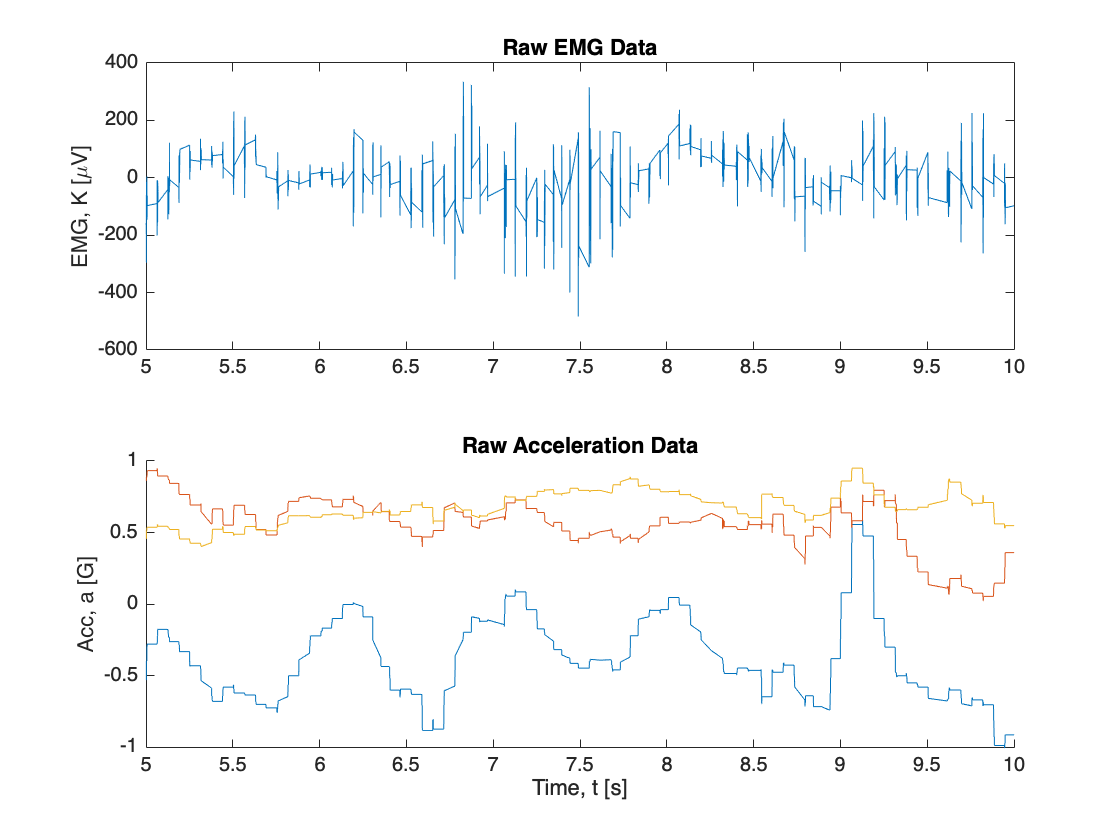

%Plot Raw EMG Data
figure();
hold on;
subplot(2,1,1)
plot(t, ch0_data)
plot(t, ch1_data) 
plot(t, ch2_data)
plot(t, ch3_data)
plot(t, ch4_data)
plot(t, ch5_data)
plot(t, ch6_data)
plot(t, ch7_data)
%legend('ch0_data','ch1_data','ch2_data','ch3_data','ch4_data','ch5_data','ch6_data','ch7_data')
%xlabel('Time, t [s]')
ylabel('EMG, K [\muV]')
title('Raw EMG Data')
xlim([5 10])

%Plot Raw EMG Data
subplot(2,1,2)
hold on;
plot(t, accx)
plot(t, accy) 
plot(t, accz)
%legend('accx','accy','accz')
xlabel('Time, t [s]')
ylabel('Acc, a [G]')
title('Raw Acceleration Data')
xlim([5 10])

Export to .txt file

% Define the folder path on desktop
folder_path = '/Users/nathandodd/Desktop/Stroke_Research/Data/Segmented_Data';

% Extract the filename without the extension
[~, name, ~] = fileparts(filename);

txt_export = [t, ch0_data, ch1_data, ch2_data, ch3_data, ch4_data, ch5_data, ch6_data, ch7_data, accx, accy, accz, round(stimulus)];

% Define the .txt filename
txt_file_name = [name, '.txt'];

column_names = {'time', 'channel1', 'channel2', 'channel3', 'channel4', 'channel5', 'channel6', 'channel7', 'channel8', 'accelx','accely', 'accelz', 'class'};


% Convert the data to a table with appropriate variable names
data_table = array2table(txt_export, 'VariableNames', column_names);

% Write the table to a text file
writetable(data_table, txt_file_name,'Delimiter', '\t');

